# Examen Final 6 (Torque y fuerzas)

Alan Iván Flores Juárez | A01736001

En esta entrega se realiza, aunado a las demás prácticas, el modelo de torque de cada articulación, la matriz de inercia, el modelo de fuerzas centripetas y de Coriolis, así como el par gravitacional de las siguientes configuraciones de robot:

## Priemer Robot

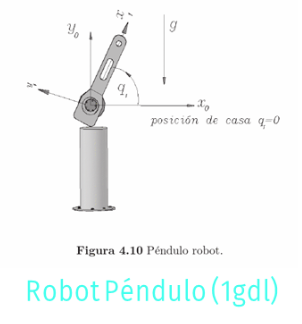 

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t)  t  %Angulos de cada articulación
syms th1p(t)   %Velocidades de cada articulación
syms th1pp(t)  %Aceleraciones de cada articulación
syms m1 Ixx1 Iyy1 Izz1 %Masas y matrices de Inercia
syms l1 lc1  %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero


En esta sección de código se realiza la declaración de todas las variables simbólicas para el cálculo de todos nuestros modelos.


 %Creamos el vector de coordenadas articulares
  Q= [th1];
 %disp('Coordenadas generalizadas');
 %pretty (Q);
 
 %Creamos el vector de velocidades articulares
  Qp= [th1p];
 %disp('Velocidades generalizadas');
 %pretty (Qp);
 %Creamos el vector de aceleraciones articulares
  Qpp= [th1pp];
 %disp('Aceleraciones generalizadas');
 %pretty (Qpp);

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0];

Se crean los vectores de cooredenadas articulares correspondientes a la posición, velocidad y aceleración, así como la declaración de nuestra junta rotacional, ya que se trata únicamente de un robot de un grado de libertad.


%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

%Articulación 1 
%Posición de la junta 1 respecto a 0
P(:,:,1)= [l1*cos(th1); l1*sin(th1); 0];%*** Vector de posición indexado por página

%Matriz de rotación de la articulación 1 respecto a 0
R(:,:,1)= [cos(th1) -sin(th1)  0; %*** Análisis de robot péndulo
           sin(th1)  cos(th1)  0;
           0         0         1];

En esta sección se realiza la traslación y rotación de nuestra articulación en base al marco de referencia elegido, y ya que en este el eje de las Z ya se encunetra alineado con nuestras articulaciones, primero se hace la traslación en X y Y, correspondiente al coseno y seno del ángulo respectivamente y posteriormente una rotación en Z de theta 1.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


Se realiza la transformación de matrices locales a globales para cada una de las articulaciones, en nuestro caso solo la primera.

for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
%     disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
%     pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
end


Se realiza el cálculo del jacobiano lineal de forma analítica.

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
%disp('Velocidad lineal obtenida mediante el Jacobiano lineal');
V=simplify (Jv_a*Qp);
%pretty(V);
%disp('Velocidad angular obtenida mediante el Jacobiano angular');
W=simplify (Jw_a*Qp);
%pretty(W);

### Energía Cinética

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Energía Cinética
%%%%%%%%%%%%%%%%%%%%%%%%%%Omitimos la división de cada lc%%%%%%%%%%%%%%%
%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
P01=subs(P(:,:,1), l1, lc1);%La función subs sustituye l1 por lc1 en 

%Creamos matrices de inercia para cada eslabón
I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

%Función de energía cinética

%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos las velocidades angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Calculamos las velocidades para cada eslabón con ayuda del jacobiano lineal obtenido de forma analítica.


%Eslabón 1
%Calculamos el jacobiano lineal y angular de forma analítica
Jv_a1(:,GDL)=PO(:,:,GDL);
Jw_a1(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1


Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1));
pretty(V1);

/ -l1 sin(th1(t)) th1p(t) \
|                         |
|  l1 cos(th1(t)) th1p(t) |
|                         |
\            0            /



disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1


W1=simplify (Jw_a1*Qp(1));
pretty(W1);

/    0    \
|         |
|    0    |
|         |
\ th1p(t) /



En este aspecto los resulados tienen sentido tanto en el aspecto de velocidad lineal como en el angular, ya que al tratarse de un robot de un solo grado de libertad con junta rotacional, corresponde una velocidad lineal en el eje X y Y, correspondiente a la longitud y seno y coseno del ángulo theta1 correspondientemente, y 0 para Z, así como una velocidad angular de 0 para X y Y, ya que esta depende de theta1 únicamente en el eje Z.

#### Calculamos la energía cinética para cada uno de los eslabones

Ya que hablamos de la energía cinética, esta va a depender de la masa de nuestra articulación y de su velocidad, dada por la ecuación de energía cinética.

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify (K1);
pretty (K1);

              2            2     ______           __                     2           2
Izz1 |th1p(t)|    |th1p(t)|  cos(th1(t) - th1(t)) m1 (l1 + lc1) (lc1 |l1|  + l1 |lc1| )
--------------- + ---------------------------------------------------------------------
       2                                         2 l1 lc1



K_Total= simplify (K1);


#### Energía Potencial para cada uno de los eslabones

En esta sección se realiza el cálculo de la energía potencial, la cual únicamente depende de la altura h1, en nuestro caso obtenida de la posción en el eje Y, la masa y la gravedad, sin depender de la velocidad como sí lo hace la energía cinética.

%Obtenemos las alturas respecto a la gravedad
 h1= P01(2); %Tomo la altura paralela al eje y

 U1=m1*g*h1;

 %Calculamos la energía potencial total
 U_Total= U1;

Conciendo ahora los valores de la energía cinética y energía potencial, podemos calular el lagrangiano, así como el modelo de energía. En caso del lagrangiano se realiza la diferencia de la energía potencial a la cinética, y para el modelo de enrgía se suman.

 %Obtenemos el Lagrangiano
 Lagrangiano= simplify (K_Total-U_Total);
 disp("Lagrangiano: ")

Lagrangiano: 


 pretty (Lagrangiano);

              2                                   2     ______           __                     2           2
Izz1 |th1p(t)|                           |th1p(t)|  cos(th1(t) - th1(t)) m1 (l1 + lc1) (lc1 |l1|  + l1 |lc1| )
--------------- - g lc1 m1 sin(th1(t)) + ---------------------------------------------------------------------
       2                                                                2 l1 lc1



 %Modelo de Energía
 H= simplify (K_Total+U_Total);
 disp("Modelo de energía: ")

Modelo de energía: 


 pretty (H)

              2                                   2     ______           __                     2           2
Izz1 |th1p(t)|                           |th1p(t)|  cos(th1(t) - th1(t)) m1 (l1 + lc1) (lc1 |l1|  + l1 |lc1| )
--------------- + g lc1 m1 sin(th1(t)) + ---------------------------------------------------------------------
       2                                                                2 l1 lc1



#### Ecuaciones de Movimiento

 %Lagrangiano derivado con respecto a la primera coordenada generalizada de
 %velocidad
 %Definimos un vector columna de derivadas con respecto al tiempo
 %En este vector agrego las velocidades y aceleraciones
  %Derivadas respecto al tiempo
 Qd=[th1p(t); th1pp(t)];

 %Obtenemos las derivadas de la velocidad en la primera coordenada
 %generalizada
 dQ1=[diff(diff(Lagrangiano,th1p), th1),... %Derivamos con respecto a la primera velocidad generalizada th1p para las 3 posiciones articulaciones
     diff(diff(Lagrangiano,th1p), th1p)];%Derivamos con respecto a la primera velocidad generalizada th1p para las 3 velocidades articulaciones

 %Definimos el torque 1
 t1= dQ1*Qd- diff(Lagrangiano, th1);


%Generación del Modelo Dinámico en forma matricial
%Extraemos coeficientes de aceleraciones
M=[diff(t1, th1pp)];
rank (M);

M=M(t);

#### Fuerzas Centrípetas y de Coriolis

Las fuerza de Coriolis representa una desviación del movimiento de traslación debido a su componente de rotación. Mientras que la fuerza centripeta es aquella fuerza que actua sobre la articulación para que se mantenga en movimiento en una trayectoria circular.

%Definimos Mp
M11=[diff(M(1,1),th1)]*Qp; %Se deriva parcialmente en el tiempo respecto a todas las variables 

Mp=[M11];


%Definimos la energía cinética en su forma matricial
k=1/2*transpose(Qp)*M*Qp;

%Definimos dk

dk=[diff(k, th1)];

%Fuerzas centrípetas y de Coriolis
 C= Mp*Qp-dk

$$C(t) = 0$$

#### Vector de par gravitacional

Podemos definir al par gravitacional como la fuerza de atracción entre los cuerpos, es decir, entre las masas.

 %Par Gravitacional

 %se sustituyen las velocidades y aceleraciones por 0
 r=cero;
 a1=subs(t1, th1p, r);
 a2=subs(a1, th1pp,r);
 %Par gravitacional motor 1
 disp("Toque gravitacional: ")

Toque gravitacional: 


 %Torque gravitacional
 G1=a2

$$G1(t) = \begin{array}{l} \mathrm{cero}\,\left(\frac{{\mathrm{Izz}}_{1}\,\left|\mathrm{cero}\right|}{\sqrt{\mathrm{cero}\,\bar{\mathrm{cero}}}}-\frac{{\mathrm{Izz}}_{1}\,\left|\mathrm{cero}\right|\,\sigma_{3}}{4\,\sigma_{4}}+\frac{{\mathrm{Izz}}_{1}\,\sigma_{3}}{4\,\mathrm{cero}\,\bar{\mathrm{cero}}}+\frac{\sigma_{2}\,\left|\mathrm{cero}\right|\,\bar{m_{1}}\,\left(l_{1}+{\mathrm{lc}}_{1}\right)\,\sigma_{1}}{l_{1}\,{\mathrm{lc}}_{1}\,\sqrt{\mathrm{cero}\,\bar{\mathrm{cero}}}}-\frac{\sigma_{2}\,\left|\mathrm{cero}\right|\,\bar{m_{1}}\,\left(l_{1}+{\mathrm{lc}}_{1}\right)\,\sigma_{1}\,\sigma_{3}}{4\,l_{1}\,{\mathrm{lc}}_{1}\,\sigma_{4}}+\frac{\sigma_{2}\,\bar{m_{1}}\,\left(l_{1}+{\mathrm{lc}}_{1}\right)\,\sigma_{1}\,\sigma_{3}}{4\,\mathrm{cero}\,l_{1}\,{\mathrm{lc}}_{1}\,\bar{\mathrm{cero}}}\right)+g\,{\mathrm{lc}}_{1}\,m_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{lc}}_{1}\,{\left|l_{1}\right|}^{2}+l_{1}\,{\left|{\mathrm{lc}}_{1}\right|}^{2}\\ \sigma_{2}=\cos\left(\bar{{\mathrm{th}}_{1}\left(t\right)}-{\mathrm{th}}_{1}\left(t\right)\right)\\ \sigma_{3}={\left(\mathrm{cero}+\bar{\mathrm{cero}}\right)}^{2}\\ \sigma_{4}={\left(\mathrm{cero}\,\bar{\mathrm{cero}}\right)}^{3/2} \end{array}$$


 % Vector de par gravitacional
 G=[G1]

$$G(t) = \begin{array}{l} \mathrm{cero}\,\left(\frac{{\mathrm{Izz}}_{1}\,\left|\mathrm{cero}\right|}{\sqrt{\mathrm{cero}\,\bar{\mathrm{cero}}}}-\frac{{\mathrm{Izz}}_{1}\,\left|\mathrm{cero}\right|\,\sigma_{3}}{4\,\sigma_{4}}+\frac{{\mathrm{Izz}}_{1}\,\sigma_{3}}{4\,\mathrm{cero}\,\bar{\mathrm{cero}}}+\frac{\sigma_{2}\,\left|\mathrm{cero}\right|\,\bar{m_{1}}\,\left(l_{1}+{\mathrm{lc}}_{1}\right)\,\sigma_{1}}{l_{1}\,{\mathrm{lc}}_{1}\,\sqrt{\mathrm{cero}\,\bar{\mathrm{cero}}}}-\frac{\sigma_{2}\,\left|\mathrm{cero}\right|\,\bar{m_{1}}\,\left(l_{1}+{\mathrm{lc}}_{1}\right)\,\sigma_{1}\,\sigma_{3}}{4\,l_{1}\,{\mathrm{lc}}_{1}\,\sigma_{4}}+\frac{\sigma_{2}\,\bar{m_{1}}\,\left(l_{1}+{\mathrm{lc}}_{1}\right)\,\sigma_{1}\,\sigma_{3}}{4\,\mathrm{cero}\,l_{1}\,{\mathrm{lc}}_{1}\,\bar{\mathrm{cero}}}\right)+g\,{\mathrm{lc}}_{1}\,m_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{lc}}_{1}\,{\left|l_{1}\right|}^{2}+l_{1}\,{\left|{\mathrm{lc}}_{1}\right|}^{2}\\ \sigma_{2}=\cos\left(\bar{{\mathrm{th}}_{1}\left(t\right)}-{\mathrm{th}}_{1}\left(t\right)\right)\\ \sigma_{3}={\left(\mathrm{cero}+\bar{\mathrm{cero}}\right)}^{2}\\ \sigma_{4}={\left(\mathrm{cero}\,\bar{\mathrm{cero}}\right)}^{3/2} \end{array}$$

Ya que en este caso el robot dispone únicamente de una articulación, el torque gravitacional de la primera articulación y el vector par gravitacional es el mismo.

## Segundo Robot

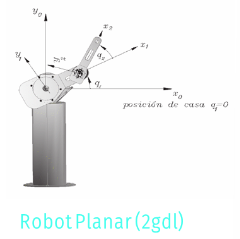

%Limpieza de pantalla
clear all
close all
clc


En esta sección de código se realiza la declaración de todas las variables simbólicas para el cálculo de todos nuestros modelos.

%Declaración de variables simbólicas
syms th1(t) th2(t)  t  %Angulos de cada articulación
syms th1p(t) th2p(t)      %Velocidades de cada articulación
syms th1pp(t) th2pp(t)    %Aceleraciones de cada articulación
syms m1 m2 m3 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 %Masas y matrices de Inercia
syms l1 l2 lc1 lc2  %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero


Se crean los vectores de cooredenadas articulares correspondientes a la posición, velocidad y aceleración, así como la declaración de nuestras juntas rotacionales, cada una dentro de su vector articular correspondiente. Así como la declaración de las dos juntas rotacionales.

 %Creamos el vector de coordenadas articulares
  Q= [th1; th2];
 %disp('Coordenadas generalizadas');
 
 %Creamos el vector de velocidades articulares
  Qp= [th1p; th2p];
 %disp('Velocidades generalizadas');
 %Creamos el vector de aceleraciones articulares
  Qpp= [th1pp; th2pp];
 %disp('Aceleraciones generalizadas');

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0];

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

De misma forma que con el primer robot, se realizan las traslaciones y rotaciones para cada una de las articulciones, y ya que ambas se encuentran en el mismo plano, su traslación depende de la longitud de la articulación correspondiente, así como del coseno para el eje X y el seno para el eje Y. Aunado a la rotación en el eje Z en ambos casos.

%Articulación 1 
%Posición de la junta 1 respecto a 0
P(:,:,1)= [l1*cos(th1); l1*sin(th1); 0];%*** Vector de posición indexado por página

%Matriz de rotación de la articulación 1 respecto a 0
R(:,:,1)= [cos(th1) -sin(th1)  0; %*** Análisis de robot péndulo
           sin(th1)  cos(th1)  0;
           0         0         1];

%Articulación 2
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [l2*cos(th2); l2*sin(th2);0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,2)= [cos(th2) -sin(th2)  0;
           sin(th2)  cos(th2)  0;
           0         0         1];



Se realizan las matrices de transformación locales a globales para cada uno de nuestros grados de libertad.

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
%     disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
%     pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end


Se realiza el cálculo del jacobiano lineal de forma analítica para cada angulo de libertad.

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
% disp('Velocidad lineal obtenida mediante el Jacobiano lineal');
V=simplify (Jv_a*Qp);
% pretty(V);
% disp('Velocidad angular obtenida mediante el Jacobiano angular');
W=simplify (Jw_a*Qp);
%     pretty(W);


#### Energía Cinética

Ya que hablamos de una energía cinética, esta va a depender de la masa de nuestra articulación y de su velocidad, definida por su fórmula.

%Se omite la división de cada lc
%Distancia del origen del eslabón a su centro de masa

%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1), l1, lc1);
 P12=subs(P(:,:,2), l2, lc2);

%Creamos matrices de inercia para cada eslabón
I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

%Función de energía cinética
%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos las velocidades angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

%Calculamos las velocidades para cada eslabón 

%Eslabón 1
%Calculamos el jacobiano lineal de forma analítica
Jv_a1(:,GDL-1)=PO(:,:,GDL-1);
Jw_a1(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
 %disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');
Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1));
 %pretty(V1);
 % disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');
W1=simplify (Jw_a1*Qp(1));
 % pretty(W1);


%Eslabón 2

%Calculamos el jacobiano lineal de forma analítica
Jv_a2(:,GDL)=PO(:,:,GDL);
Jw_a2(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a2(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a2(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)=[0,0,1];
        end
            Jw_a2(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a2= simplify (Jv_a2);
Jw_a2= simplify (Jw_a2);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac2= [Jv_a2;
      Jw_a2];
Jacobiano2= simplify(Jac2);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
%disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2');
V2=simplify (Jv_a2*Qp(1:2));
% pretty(V2);
%disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2');
W2=simplify (Jw_a2*Qp(1:2));
% pretty(W2);


Una vez habiendo calculado y conociendo las velocidades lineales y angulares para cada una de nuestras articulaciones, podemos proceder a calcular la energía cinética.

%Calculamos la energía cinética para cada uno de los eslabones
%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
%disp('Energía Cinética en el Eslabón 1');
K1= simplify (K1);
%pretty (K1);

%Eslabón 2
V2_Total= V2+cross(W2,P12);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W2)'*(I2*W2);
%disp('Energía Cinética en el Eslabón 2');
K2= simplify (K2);
%pretty (K2);

K_Total= simplify (K1+K2);
disp('Energía Cinética total')
pretty (K_Total);


#### Energía potencial

En esta sección se realiza el cálculo de la energía potencial, la cual depende de la altura h1 y h2, en nuestro caso obtenida de la posción de cada uno de las articulaciones en el eje Y, su masa y la gravedad, sin depender de su velocidad como sí lo hace la energía cinética.

%Calculamos la energía potencial para cada uno de los eslabones

%Obtenemos las alturas respecto a la gravedad
 h1= P01(2); %Tomo la altura paralela al eje y
 h2= P12(2); %Tomo la altura paralela al eje y

 U1=m1*g*h1;
 U2=m2*g*h2;

 %Calculamos la energía potencial total
 U_Total= U1 + U2;

Conciendo ahora los valores de la energía cinética y energía potencial, podemos calular el lagrangiano, así como el modelo de energía. En caso del lagrangiano se realiza la diferencia de la energía potencial a la cinética.

 %Obtenemos el Lagrangiano
 disp("Lagrangiano: ")
 Lagrangiano= simplify (K_Total-U_Total);
 %pretty (Lagrangiano);

Y en el caso del modelo de energía se realiza su suma.

%Modelo de Energía
 disp("Modelo de energía: ")
 H= simplify (K_Total+U_Total);
 pretty (H)


#### Ecuaciones de movimiento

 %Lagrangiano derivado con respecto a la primera coordenada generalizada de
 %velocidad

 %Definimos un vector columna de derivadas con respecto al tiempo
 %En este vector agrego las velocidades y aceleraciones

  %Derivadas respecto al tiempo
 Qd=[th1p(t); th2p(t); th1pp(t); th2pp(t)];

 %Obtenemos las derivadas de la velocidad en la primera coordenada
 %generalizada
 dQ1=[diff(diff(Lagrangiano,th1p), th1),diff(diff(Lagrangiano,th1p), th2),... %Derivamos con respecto a la primera velocidad generalizada th1p para las 3 posiciones articulaciones
     diff(diff(Lagrangiano,th1p), th1p),diff(diff(Lagrangiano,th1p), th2p)];%Derivamos con respecto a la primera velocidad generalizada th1p para las 3 velocidades articulaciones

 %Definimos el torque 1
 t1= dQ1*Qd- diff(Lagrangiano, th1);


 %Obtenemos las de derivadas de la velocidad en la segunda coordenada
 %generalizada

 dQ2=[diff(diff(Lagrangiano,th2p), th1),diff(diff(Lagrangiano,th2p), th2),... %Derivamos con respecto a la segunda velocidad generalizada th2p para las 3 posiciones articulaciones
     diff(diff(Lagrangiano,th2p), th1p),diff(diff(Lagrangiano,th2p), th2p)];%Derivamos con respecto a la segunda velocidad generalizada th2p para las 3 velocidades articulaciones

 %Definimos el torque 2
 t2= dQ2*Qd- diff(Lagrangiano, th2);

 %Generación del Modelo Dinámico en forma matricial

%Matriz de Inercia
%Extraemos coeficientes de aceleraciones

M=[diff(t1, th1pp), diff(t1, th2pp);...
   diff(t2, th1pp), diff(t2, th2pp)];
rank (M);

M=M(t);


####  Fuerzas Centrípetas y de Coriolis

Las fuerza de Coriolis representa una desviación del movimiento de traslación debido a su componente de rotación. Mientras que la fuerza centripeta es aquella fuerza que actua sobre la articulación para que se mantenga en movimiento en una trayectoria circular.


 %Definimos Mp

 M11=[diff(M(1,1),th1), diff(M(1,1),th2)]*Qp;%Se deriva parcialmente en el tiempo respecto a todas las variables 
 M12=[diff(M(1,2),th1), diff(M(1,2),th2)]*Qp;

 M21=[diff(M(2,1),th1), diff(M(2,1),th2)]*Qp;
 M22=[diff(M(2,2),th1), diff(M(2,2),th2)]*Qp;

  Mp=[M11, M12;...
      M21, M22];


%Definimos la energía cinética en su forma matricial
k=1/2*transpose(Qp)*M*Qp;

%Definimos dk

dk=[diff(k, th1); diff(k, th2)];

%Fuerzas centrípetas y de Coriolis
 C= Mp*Qp-dk;


 %Par Gravitacional
 %se sustituyen las velocidades y aceleraciones por 0
 r=cero;
 a1=subs(t1, th1p, r);
 a2=subs(a1, th2p, r);
 a3=subs(a2, th1pp,r);
 a4=subs(a3, th2pp,r);

 %Torque gravitacional en el motor 1
 G1=a4;

 
 b1=subs(t2, th1p, r);
 b2=subs(b1, th2p, r);
 b3=subs(b2, th1pp,r);
 b4=subs(b3, th2pp,r);

 %Torque gravitacional en el motor 2
 G2=b4;

% Vector de par gravitacional

G=[G1;G2]

En este caso el vector de par gravitacional corresponde al vector del torque gravitacional ejercido sobre cada una de las articulaciones, en este caso G1 y G2.